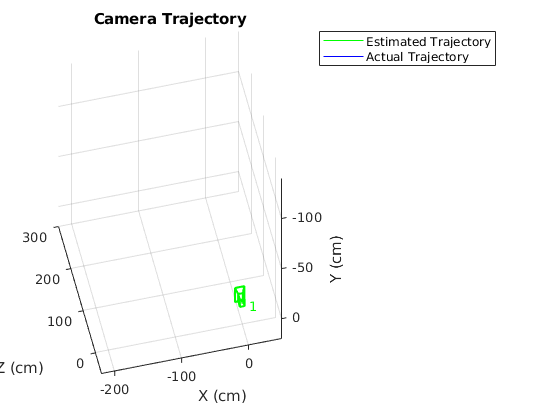

load('groundTruthPoses.mat');
% Create an empty imageviewset object to manage the data associated with each view.
vSet = imageviewset;

% Read and display the first image.

images= imageDatastore('imgseq');
Irgb=readimage(images,1);

calibrationData = load('camera_params_camvid.mat');

% Describe camera configuration.
focalLength    = calibrationData.cameraParams.FocalLength;
principalPoint = calibrationData.cameraParams.PrincipalPoint;
imageSize      = calibrationData.cameraParams.ImageSize;
intrinsics = cameraIntrinsics(focalLength, principalPoint, imageSize);

prevI = undistortImage(rgb2gray(Irgb), intrinsics); 

% Detect features. 
prevPoints = detectSURFFeatures(prevI, 'MetricThreshold', 500);

% Select a subset of features, uniformly distributed throughout the image.
numPoints = 200;
prevPoints = selectUniform(prevPoints, numPoints, size(prevI));

% Extract features. Using 'Upright' features improves matching quality if 
% the camera motion involves little or no in-plane rotation.
prevFeatures = extractFeatures(prevI, prevPoints, 'Upright', true);

% Add the first view. Place the camera associated with the first view
% at the origin, oriented along the Z-axis.
viewId = 1;


vSet = addView(vSet, viewId, rigid3d(eye(3), [0 0 0]), 'Points', prevPoints);

% Setup axes.
figure
axis([-220, 50, -140, 20, -50, 300]);

% Set Y-axis to be vertical pointing down.
view(gca, 3);
set(gca, 'CameraUpVector', [0, -1, 0]);
camorbit(gca, -120, 0, 'data', [0, 1, 0]);

grid on
xlabel('X (cm)');
ylabel('Y (cm)');
zlabel('Z (cm)');
hold on

% Plot estimated camera pose. 
cameraSize = 7;
camPose = poses(vSet);
camEstimated = plotCamera(camPose, 'Size', cameraSize,...
    'Color', 'g', 'Opacity', 0);


% Initialize camera trajectories.
trajectoryEstimated = plot3(0, 0, 0, 'g-');
trajectoryActual    = plot3(0, 0, 0, 'b-');

legend('Estimated Trajectory', 'Actual Trajectory');
title('Camera Trajectory');

% Read and display the image.
viewId = 2;
Irgb = readimage(images,viewId);

% Convert to gray scale and undistort.
I = undistortImage(rgb2gray(Irgb), intrinsics);

% Match features between the previous and the current image.
[currPoints, currFeatures, indexPairs] = helperDetectAndMatchFeatures(...
    prevFeatures, I);

% Estimate the pose of the current view relative to the previous view.
[orient, loc, inlierIdx] = helperEstimateRelativePose(...
    prevPoints(indexPairs(:,1)), currPoints(indexPairs(:,2)), intrinsics);

% Exclude epipolar outliers.
indexPairs = indexPairs(inlierIdx, :);
    
% Add the current view to the view set.
vSet = addView(vSet, viewId, rigid3d(orient, loc), 'Points', currPoints);

% Store the point matches between the previous and the current views.
vSet = addConnection(vSet, viewId-1, viewId, 'Matches', indexPairs);


vSet = helperNormalizeViewSet(vSet, groundTruthPoses);

helperUpdateCameraPlots(viewId, camEstimated, poses(vSet));
helperUpdateCameraTrajectories(viewId, trajectoryEstimated, poses(vSet));


prevI = I;
prevFeatures = currFeatures;
prevPoints   = currPoints;

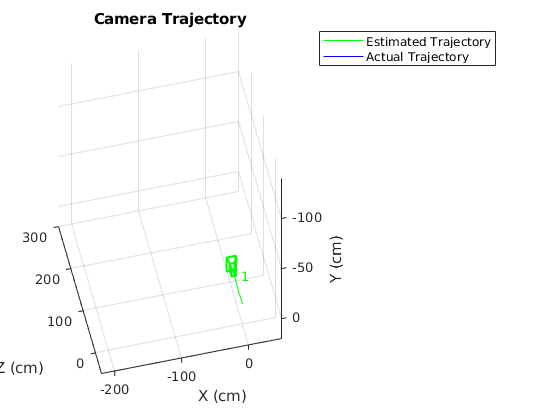


for viewId = 3:15
    % Read and display the next image
    Irgb = readimage(images,viewId);
    
    % Convert to gray scale and undistort.
    I = undistortImage(rgb2gray(Irgb), intrinsics);
    
    % Match points between the previous and the current image.
    [currPoints, currFeatures, indexPairs] = helperDetectAndMatchFeatures(...
        prevFeatures, I);
      
    % Eliminate outliers from feature matches.
    inlierIdx = helperFindEpipolarInliers(prevPoints(indexPairs(:,1)),...
        currPoints(indexPairs(:, 2)), intrinsics);
    indexPairs = indexPairs(inlierIdx, :);
    
    % Triangulate points from the previous two views, and find the 
    % corresponding points in the current view.
    [worldPoints, imagePoints] = helperFind3Dto2DCorrespondences(vSet,...
        intrinsics, indexPairs, currPoints);
    
    % Since RANSAC involves a stochastic process, it may sometimes not
    % reach the desired confidence level and exceed maximum number of
    % trials. Disable the warning when that happens since the outcomes are
    % still valid.
    warningstate = warning('off','vision:ransac:maxTrialsReached');
    
    % Estimate the world camera pose for the current view.
    [orient, loc] = estimateWorldCameraPose(imagePoints, worldPoints, intrinsics);
    
    % Restore the original warning state
    warning(warningstate)
    
    % Add the current view to the view set.
    vSet = addView(vSet, viewId, rigid3d(orient, loc), 'Points', currPoints);
    
    % Store the point matches between the previous and the current views.
    vSet = addConnection(vSet, viewId-1, viewId, 'Matches', indexPairs);    
    
    tracks = findTracks(vSet); % Find point tracks spanning multiple views.
        
    camPoses = poses(vSet);    % Get camera poses for all views.
    
    % Triangulate initial locations for the 3-D world points.
    xyzPoints = triangulateMultiview(tracks, camPoses, intrinsics);
    
    % Refine camera poses using bundle adjustment.
    [~, camPoses] = bundleAdjustment(xyzPoints, tracks, camPoses, ...
        intrinsics, 'PointsUndistorted', true, 'AbsoluteTolerance', 1e-12,...
        'RelativeTolerance', 1e-12, 'MaxIterations', 200, 'FixedViewID', 1);
        
    vSet = updateView(vSet, camPoses); % Update view set.
    
    % Bundle adjustment can move the entire set of cameras. Normalize the
    % view set to place the first camera at the origin looking along the
    % Z-axes and adjust the scale to match that of the ground truth.
    vSet = helperNormalizeViewSet(vSet, groundTruthPoses);
    
    % Update camera trajectory plot.
   
    helperUpdateCameraPlots(viewId, camEstimated, poses(vSet));
    helperUpdateCameraTrajectories(viewId, trajectoryEstimated, poses(vSet));

    prevI = I;
    prevFeatures = currFeatures;
    prevPoints   = currPoints;  
end

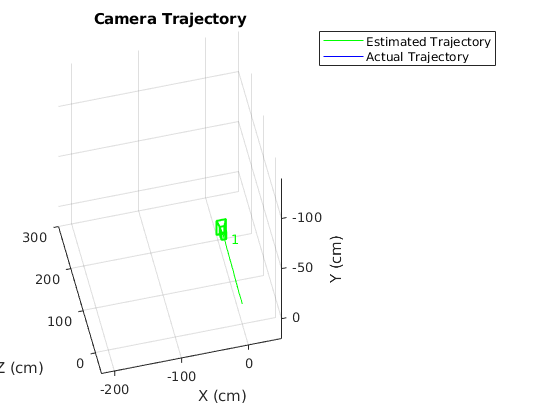


for viewId = 16:30
    % Read and display the next image
    Irgb = readimage(images,viewId);
    
    % Convert to gray scale and undistort.
    I = undistortImage(rgb2gray(Irgb), intrinsics);

    % Match points between the previous and the current image.
    [currPoints, currFeatures, indexPairs] = helperDetectAndMatchFeatures(...
        prevFeatures, I);    
          
    % Triangulate points from the previous two views, and find the 
    % corresponding points in the current view.
    [worldPoints, imagePoints] = helperFind3Dto2DCorrespondences(vSet, ...
        intrinsics, indexPairs, currPoints);

    % Since RANSAC involves a stochastic process, it may sometimes not
    % reach the desired confidence level and exceed maximum number of
    % trials. Disable the warning when that happens since the outcomes are
    % still valid.
    warningstate = warning('off','vision:ransac:maxTrialsReached');
    
    % Estimate the world camera pose for the current view.
    [orient, loc] = estimateWorldCameraPose(imagePoints, worldPoints, intrinsics);
    
    % Restore the original warning state
    warning(warningstate)
    
    % Add the current view and connection to the view set.
    vSet = addView(vSet, viewId, rigid3d(orient, loc), 'Points', currPoints);
    vSet = addConnection(vSet, viewId-1, viewId, 'Matches', indexPairs);
        
    % Refine estimated camera poses using windowed bundle adjustment. Run 
    % the optimization every 7th view.
    if mod(viewId, 3) == 0        
        % Find point tracks in the last 15 views and triangulate.
        windowSize = 40;
        startFrame = max(1, viewId - windowSize);
        tracks = findTracks(vSet, startFrame:viewId);
        camPoses = poses(vSet, startFrame:viewId);
        [xyzPoints, reprojErrors] = triangulateMultiview(tracks, camPoses, intrinsics);
                                
        % Hold the first two poses fixed, to keep the same scale. 
        fixedIds = [startFrame, startFrame+1];
        
        % Exclude points and tracks with high reprojection errors.
        idx = reprojErrors < 2;
        
        [~, camPoses] = bundleAdjustment(xyzPoints(idx, :), tracks(idx), ...
            camPoses, intrinsics, 'FixedViewIDs', fixedIds, ...
            'PointsUndistorted', true, 'AbsoluteTolerance', 1e-12,...
            'RelativeTolerance', 1e-12, 'MaxIterations', 200);
        
        vSet = updateView(vSet, camPoses); % Update view set.
    end
    
    % Update camera trajectory plot.
    
    helperUpdateCameraPlots(viewId, camEstimated, poses(vSet));
    helperUpdateCameraTrajectories(viewId, trajectoryEstimated, poses(vSet));

    prevI = I;
    prevFeatures = currFeatures;
    prevPoints   = currPoints;  
end